# Actividad1 Mapeo

Alan Iván Flores Juárez | A01736001

### Objetivo

Implementar el código requerido para generar un mapeo del siguiente sistema global al sistema local de referencia del robot móvil y viceversa.

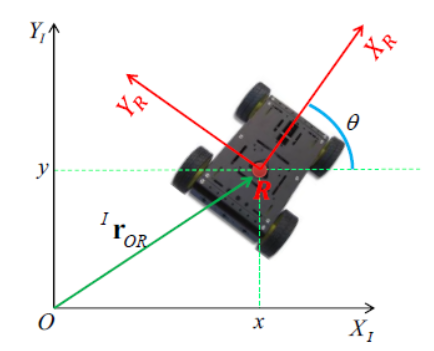

### Pasos a seguir

Se declaran las variables simbólicas con los grados de libertad del robot, así como los vectores de posición y velocidad.

%Declaración de variables simbólicas
syms x(t) y(t) th(t)  t  %Grados de Libertad del robot móvil

 %Creamos el vector de posición
  xi_inercial= [x; y; th];
  disp('Coordenadas generalizadas');

Coordenadas generalizadas


  pretty (xi_inercial);

/  x(t) \
|       |
|  y(t) |
|       |
\ th(t) /




 %Creamos el vector de velocidades
  xip_inercial= diff(xi_inercial, t);
  disp('Velocidades generalizadas');

Velocidades generalizadas


  pretty (xip_inercial);

/   d      \
|  -- x(t) |
|  dt      |
|          |
|   d      |
|  -- y(t) |
|  dt      |
|          |
|  d       |
| -- th(t) |
\ dt       /



Posteriormente se realiza la definen los vectores de posición y de rotación, dependiendo de los valores de x,y y el ángulo para la posición, y de la matriz de rotación para el eje z.

  %Defino mi vector de posición y matriz de rotación
P(:,:,1)= [x;y;th]; %Viene siendo "xi_inercial"
%Matriz de rotación alrededor del eje z.... 
R(:,:,1)= [cos(th) -sin(th)  0;
           sin(th)  cos(th)  0;
           0        0        1];

Posteriormente se realiza la transformación del marco de referencia global al local, esto se hace con la multiplicación de ambos vectores de rotación y posición respectivamente.

%Realizo mi transformación del marco de referencia global al local.... 
xi_local=R(:,:,1)*P(:,:,1)

$$xi\_local = \left(\begin{array}{c} \cos\left(\mathrm{th}\left(t\right)\right)\,x\left(t\right)-\sin\left(\mathrm{th}\left(t\right)\right)\,y\left(t\right)\\ \cos\left(\mathrm{th}\left(t\right)\right)\,y\left(t\right)+\sin\left(\mathrm{th}\left(t\right)\right)\,x\left(t\right)\\ \mathrm{th}\left(t\right) \end{array}\right)$$

Posteriormene se realizan las definciones de las coordenas inerciales, son estas las que se modificaran posteriormente y se comprobará que se obtienen las coordenadas iniciales con el mapeo inverso.

%Defino coordenadas inerciales para un tiempo 1
x1 = -5;    % Posicion inicial eje x
y1 = 9;  % Posicion inicial eje y
th1= -2;   % Orientacion inicial del robot

Se repite la definicion de un vector de posición y rotación, esta vez para un tiempo 1 y se obtiene su magnitud.

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1=[x1; y1; th1];
Rot_1= [cos(th1) -sin(th1) 0;
        sin(th1)  cos(th1) 0;
        0         0      1];
 
%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1=Rot_1*Pos_1

xi_local_1 =    10.2644
    0.8012
   -2.0000



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1(1)^2 + xi_local_1(2)^2)

magnitud = 10.2956

Por último se comprueba que el resultado sea correcto.

%Compruebo que me devuelva el vector inercial 
inv_Rot_1= inv(Rot_1);
xi_inercial_1= inv_Rot_1*xi_local_1

xi_inercial_1 =    -5.0000
    9.0000
   -2.0000


#### Coordenadas inerciales a obtener

a) (-5,9,-2°)

b) (-3,8,63°)

c) (5, -2, 90°)

d) (0, 0, 180°)

e) (-6,3,-55°)

f) (10, -2, 45°)

g) (9, 1, 88°)

h) (5, 2, 33°)

i) (-1, -1, 21°)

j) (6,4,-40°)

k) (5,7,72°)

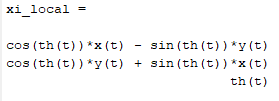

l) (7,7,30°)

m) (11,-4,360°)

n) (20, 5, 270°)

ñ) (10, 9, 345°)

o) (-9, -8, 8°)

p) (1, 1, 60°)

q) (3, 1, -30°)

r) (15, 2, 199°)

s) (-10, 0, 300°)